Frequency:

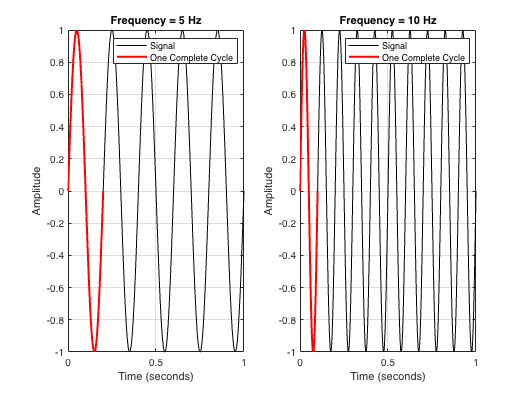

clear; clc;
fs = 1000;
duration = 1;

f1 = 5;
f2 = 10;

t = 0:1/fs:duration;

signal1 = sin(2*pi*f1*t);
signal2 = sin(2*pi*f2*t);

figure;
subplot(1, 2, 1);
plot(t, signal1, 'black');
title(['Frequency = ' num2str(f1) ' Hz']);
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;

hold on;
t_cycle1 = 0:1/fs:(1/f1);
cycle1 = sin(2*pi*f1*t_cycle1);
plot(t_cycle1, cycle1, 'r', 'LineWidth', 2);
legend('Signal', 'One Complete Cycle');
hold off;

subplot(1, 2, 2);
plot(t, signal2, 'black');
title(['Frequency = ' num2str(f2) ' Hz']);
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;

hold on;
t_cycle2 = 0:1/fs:(1/f2);
cycle2 = sin(2*pi*f2*t_cycle2);
plot(t_cycle2, cycle2, 'r', 'LineWidth', 2);
legend('Signal', 'One Complete Cycle');
hold off;

Amplitude:

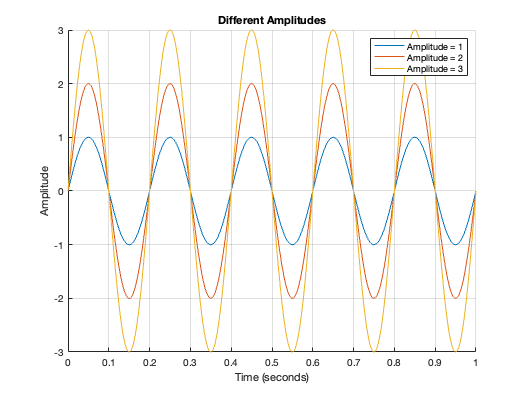

fs = 1000;
duration = 1;
f = 5;
amplitudes = [1, 2, 3];

t = 0:1/fs:duration;

figure;
hold on;

for i = 1:length(amplitudes)
    signal = amplitudes(i) * sin(2*pi*f*t);
    
    plot(t, signal, 'DisplayName', ['Amplitude = ' num2str(amplitudes(i))]);
end

title('Different Amplitudes');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;
legend;
hold off;

Phase:

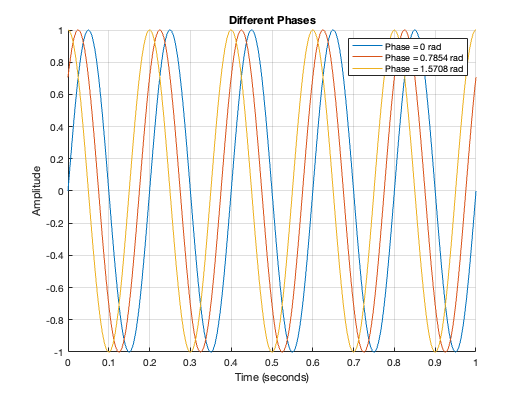

fs = 1000;
duration = 1;
f = 5;
phases = [0, pi/4, pi/2];

t = 0:1/fs:duration;
›
figure;
hold on;

for i = 1:length(phases)
    signal = sin(2*pi*f*t + phases(i));
    
    plot(t, signal, 'DisplayName', ['Phase = ' num2str(phases(i)) ' rad']);
end

title('Different Phases');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;
legend;
hold off;